# TPMS Generator 

----------------------------------------

Daniel Morton

clear; close all; clc; 

## INPUTS

----------------

#### Defining the period of the function: 

For a cubic domain, keep x,y,z periods uniform. Otherwise, if a non-cubic domain is desired, change these individually

UniformPeriod = 3; 
x_period = UniformPeriod;
y_period = UniformPeriod;
z_period = UniformPeriod;

#### Defining the grid resolution: 

For a finer mesh, make this smaller (this increases STL file size/complexity though)

gridres = .35;

#### Selecting TPMS type

Type 's' for Schwarz, 'g' for Gyroid, 'd' for Diamond

TPMSchar = 'g'; 

#### Defining isovalue

Define function value in space at which to build the surface. Typically 0. Values not equal to 0 will bias the flow domain volumes more towards one fluid versus another

isovalue = 0;

#### Defining rotation:

Define reference vector and vector to be rotated towards. vector1 usually is [0;0;1]. Typical values for vector 2 include [1;1;1] and [1;1;0] -  though others can be solved for. Keep vector2 at [0;0;1] for no rotation

vector1 = [0;0;1];  % Note: Using column vectors
vector2 = [1;1;0]; 

#### Selecting thin surface vs solid

Input 0 for a thin surface or 1 for a solid region

checkThick = 1; % change value as desired

#### Defining solid thickness (if above value is defined for a solid structure)

solidThickness = pi/6; 

## Create grid domain in x,y,z 

These are period multiples of pi for continuity - if a specific structure domain dimension is desired, let the x,y,z periods equal (desired length)/(2*pi)

% [x,y,z] = meshgrid(0:gridres:x_period*2*pi, 0:gridres:y_period*2*pi, 0:gridres:z_period*2*pi);

% Below function plots domain centered around (0,0,0)
[x,y,z] = meshgrid(-x_period*pi:gridres:x_period*pi, -y_period*pi:gridres:y_period*pi, -z_period*pi:gridres:z_period*pi);

## Calculating Rotated Vectors and Components 

% Calculate axis-angle rotation. First 3 elements define the rotation axis; the fourth defines angle 
r = vrrotvec(vector1,vector2);  

% Calculate the rotation matrix from the axis-angle method
m = vrrotvec2mat(r); 

newXcomponents = m*[1;0;0];
newYcomponents = m*[0;1;0];
newZcomponents = m*[0;0;1]; 

xNew = newXcomponents(1)*x + newXcomponents(2)*y + newXcomponents(3)*z; 
yNew = newYcomponents(1)*x + newYcomponents(2)*y + newYcomponents(3)*z; 
zNew = newZcomponents(1)*x + newZcomponents(2)*y + newZcomponents(3)*z; 


## Create TPMS function using grid domains x,y,z

% % Gyroid  = cos(x) .* sin(y) + cos(y) .* sin(z) + cos(z) .* sin(x);
% % Schwarz = cos(x) + cos(y) + cos(z); 
% % Diamond = sin(x).*sin(y).*sin(z) + sin(x).*cos(y).*cos(z) + cos(x).*sin(y).*cos(z) + cos(x).*cos(y).*sin(z); 

GyroidNew  = cos(xNew) .* sin(yNew) + cos(yNew) .* sin(zNew) + cos(zNew) .* sin(xNew);
SchwarzNew = cos(xNew) + cos(yNew) + cos(zNew); 
DiamondNew = sin(xNew).*sin(yNew).*sin(zNew) + sin(xNew).*cos(yNew).*cos(zNew) + cos(xNew).*sin(yNew).*cos(zNew) + cos(xNew).*cos(yNew).*sin(zNew); 

GyroidNewThick = abs( GyroidNew ) - solidThickness; 
SchwarzNewThick = abs( SchwarzNew ) - solidThickness; 
DiamondNewThick = abs( DiamondNew ) - solidThickness; 

% ^ "New" versions implement rotation
% "Thick" versions include solid domain

## Defining the TPMS type based on user input

if TPMSchar == 's' || TPMSchar == 'S'
    if checkThick == 0
        volumeData = SchwarzNew; 
    else
        volumeData = SchwarzNewThick; 
    end
    
elseif TPMSchar == 'g'  || TPMSchar == 'G'
    if checkThick == 0
        volumeData = GyroidNew; 
    else
        volumeData = GyroidNewThick; 
    end
    
elseif TPMSchar == 'd' || TPMSchar == 'D'
    if checkThick == 0
        volumeData = DiamondNew; 
    else
        volumeData = DiamondNewThick; 
    end
    
    volumeData = DiamondNew;
else
    disp('Error: incorrect TPMS type input')
end

## Creating isosurface faces and vertices

% f, v represent faces and vertices in separate structs
% Isosurface() creates surface at all points in space equal to the isovalue, 
% based on the points in domain and the function being modeled

[f,v] = isosurface(x,y,z,volumeData,isovalue);
[f2,v2,c2] = isocaps(x,y,z,volumeData,isovalue, 'enclose', 'below');
% enclose 'above' is the default, below gives the correct thin-walled
% structure though, since the 3d domain is negative in that region

% Isocaps faces and vertices
f3 = [f ; f2+length(v(:,1))];
v3 = [v ; v2];

## Write STLs

Note: If exporting STLs, make sure the stlwrite file is in the same folder as the matlab script

Generating automatic file names:

if checkThick == 0
    thickOrThin = 'thin'
else
    thickOrThin = 'thick'
end

thickOrThin = 'thick'


str1 = [ TPMSchar, string(vector2(1:3))', thickOrThin, '_', datestr(now, 30), '.stl' ];
filename1 = convertStringsToChars( join(str1, '') )

filename1 = 'g110thick_20200816T235153.stl'


str2 = [ TPMSchar, string(vector2(1:3))', thickOrThin, '_capped_' ,datestr(now, 30), '.stl' ];
filename2 = convertStringsToChars( join(str2, '') )

filename2 = 'g110thick_capped_20200816T235153.stl'

Writing the STLs

stlwrite(filename1,f,v);                   % Surface only, no end caps

Wrote 3 faces


stlwrite(filename2,f3,v3);                 % Surface with end caps

Wrote 3 faces


## Plotting in 3D 

#### Surface only:

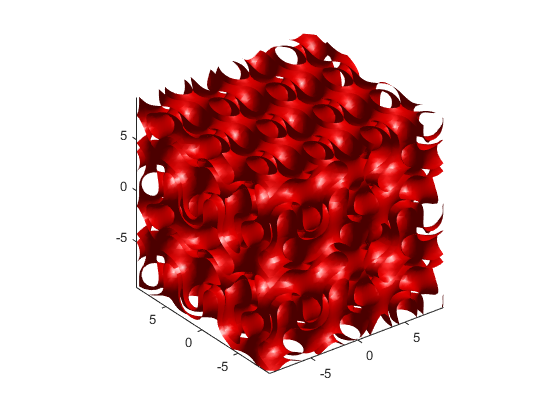

figure(1)
p1 = patch('Faces',f,'Vertices',v);
set(p1,'FaceColor','red','EdgeColor','none');             % set colors
daspect([1,1,1])                                          % uniform aspect ratio
view(3); axis tight
camlight; lighting gouraud

#### Surface with caps (only plotted if thick TPMS is desired):

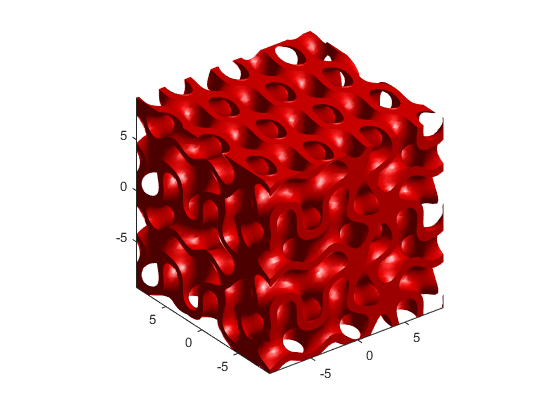

if checkThick ~= 0
    figure(2)
    p2 = patch('Faces',f3,'Vertices',v3);
    set(p2,'FaceColor','red','EdgeColor','none');             % set colors
    daspect([1,1,1])                                          % uniform aspect ratio
    view(3); axis tight
    camlight; lighting gouraud
end